# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{
    
    run_ge.mlx
    ----------

    This code runs all codes to solve the decentralized model.
	
%}

## Model: Decentralized Model.

The model is solved as decentralized problem. The household's problem is


$$\underset{\{c_t\}_{t=0}^{\infty},\{a_{t+1}\}_{t=0}^{\infty}}{\text{max }} \mathbb{E}_0 \sum_{t=0}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } c_t + a_{t+1} = (1+r)a_t + wl_te^{z_t} \ ,$$


 
$$z_{t+1} = \mu + \rho z_t + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0 \ , \\
a_t \geq \phi \ , $$



$$a_t \ \text{is given} \ ,$$


where $w$ is the wage rate that households take as given, $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints hold for $t = 1, 2, ...,$. The firm's problem is static and given by


$$\underset{k_t,l_t}{\text{max }} k_t^{\alpha}l_t^{1-\alpha} - wl_t - r_tk_t \text{ ,}$$


 
$$\text{s.t.} \ k_{t+1} = (1-\delta)k_t + i_t \ .$$


Firms are perfectly competitive so prices are


$$r = \alpha k_t^{\alpha-1}l_t^{1-\alpha}-\delta \ ,$$



$$w = (1-\alpha)k^{\alpha} l^{\alpha}\ .$$


Normalizing labor supply such that $l_t = 1$, prices in steady state (where variables have "settled down") are


$$y^* = {k^*}^{\alpha} \ , \\
i^* = \delta k^* \ ,$$



$$r = \alpha {k^*}^{\alpha-1}-\delta \ ,$$



$$w = (1-\alpha){k^*}^{\alpha} \ .$$


In the steady-state equilibrium, the asset market clears so the saving supplied by households equals the capital demanded by firms


$$k = \int a(z,r,w) \ dF(a) \approx \sum_{i=1}^N a_i(z,r,w) \ .$$


The equilibrium consists of (i) optimal policy functions given $r$ and $w$, (ii) steady-state distributions consistent with the optimal policy functions, and (iii) labor and captial markets clearing.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:/Users/',id,'/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/05_ge/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

fprintf('The directory is %s \n\n',main)

The directory is C:/Users/xmgb/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/05_ge/ 



## Set the parameters and generate the state space.

Note that the firm's problem is static and if we are able to solve for $r$, then we can back out $k$ and solve for $w$.

Calls: model.m.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model in partial equilibrium.

Solve the model taking prices as given but with out checking if markets clear, then plot the distribution of wealth.

Calls: solve.m, simulate.m, my_graph.m

[par,sol] = solve.firm_problem(par); % Firms.
sol = solve.hh_problem(par,sol); % Households.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 268 iterations.

------------End of Value Function Iteration.------------


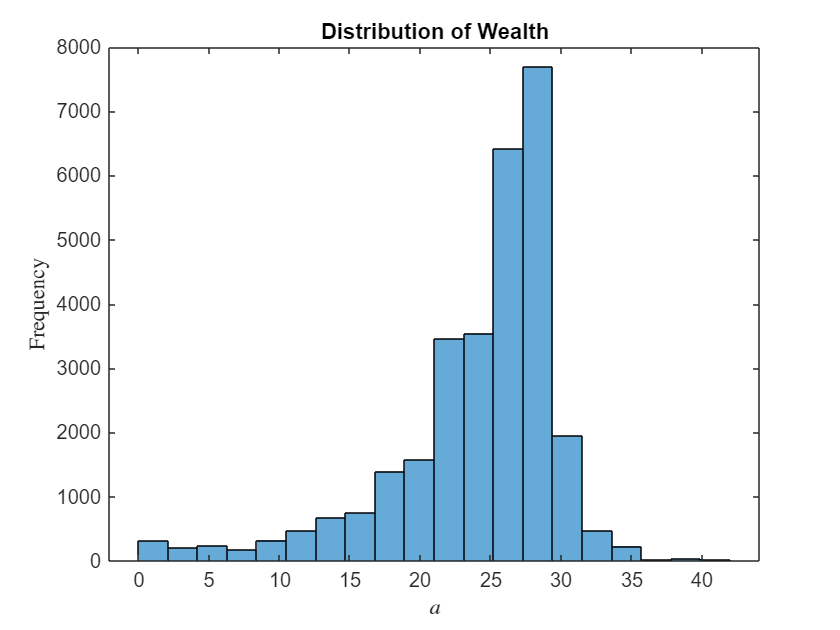

sim = simulate.economy(par,sol); % Simulate the economy.
my_graph.plot_dist_pe(sim) % Plot the distribution of wealth.

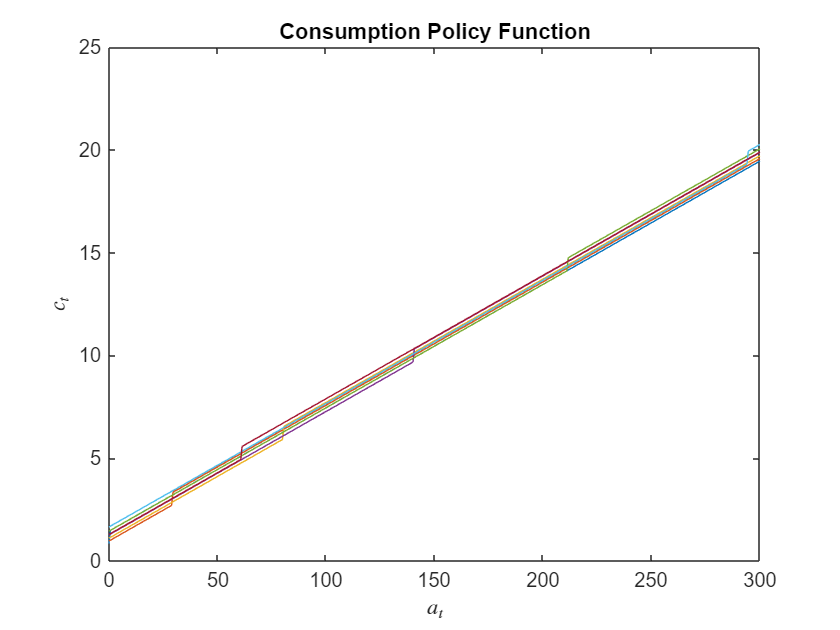

my_graph.cfun(par,sol) % Plot the consumption function.

## Solve the model in general equilibrium.

Solve the model taking prices, where prices adjust so that markets clear, then plot the distribution of wealth.

Calls: solve.m, simulate.m, my_graph.m

find_prices = @(r0)(equilibrium.obj_fun(r0,par)); % Find the value of r that sets supply equal demand.
r_eq = fminbnd(find_prices,-par.delta,(1/par.beta)-1); % Equilibrium r.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 267 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 271 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 274 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iterat

par_ge = par;
par_ge.r = r_eq;
[par_ge,sol_ge] = solve.firm_problem(par_ge); % Firms.
sol_ge = solve.hh_problem(par_ge,sol_ge); % Households.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 271 iterations.

------------End of Value Function Iteration.------------


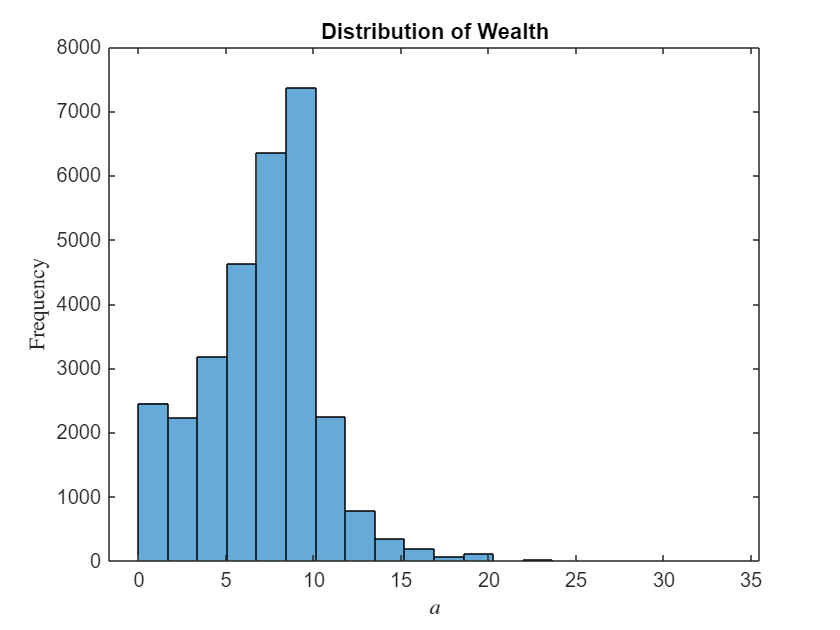

sim_ge = simulate.economy(par_ge,sol_ge); % Simulate the economy.

my_graph.plot_dist_ge(sim_ge) % Plot the distribution of wealth.

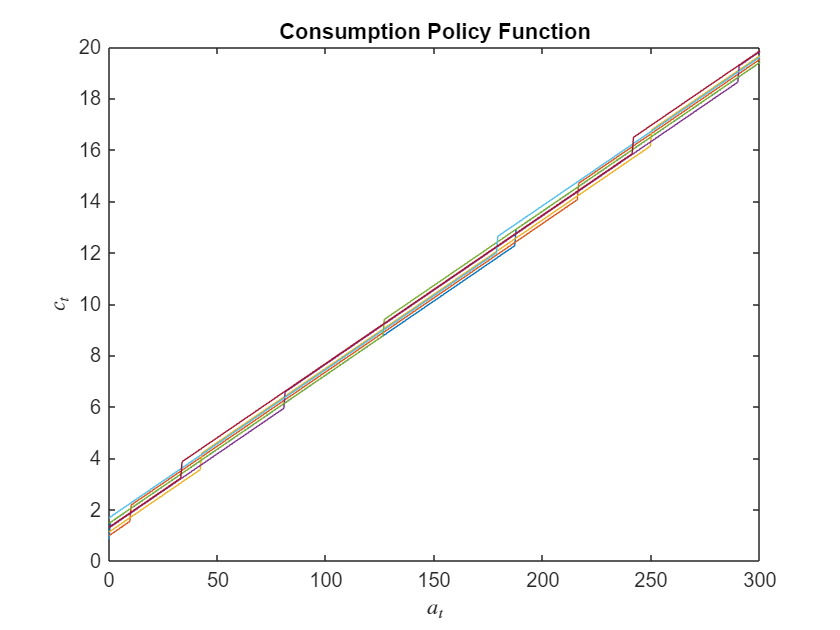

my_graph.cfun(par_ge,sol_ge) % Plot the consumption function.